clc; clear all; close all;

img_path = fullfile('Codes','fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

RGB = imread(string(fullfile(img_path, T{4,1})));%Aquí elijes la imagen
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
maxR=max(R(:));
maxG=max(G(:));
maxB=max(B(:)); 

figure;

imshow((RGB));

figure;

imshow(RGB(:,:,1),[0.9*maxR maxR]);

figure;

imshow(RGB(:,:,2),[0.4*maxG maxG]);

figure;

imshow(RGB(:,:,3),[0.4*maxB maxB]);

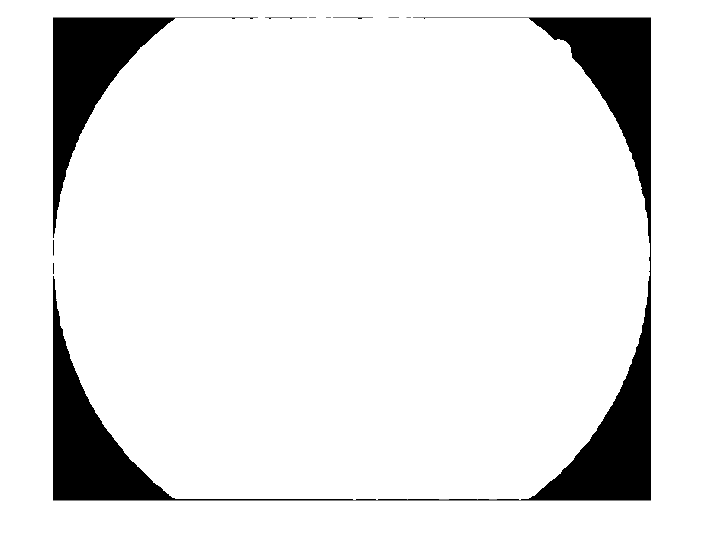

originalImage=double(rgb2gray(RGB));
originalImage = medfilt2(originalImage, [20 20]);
figure;
imshow(originalImage);

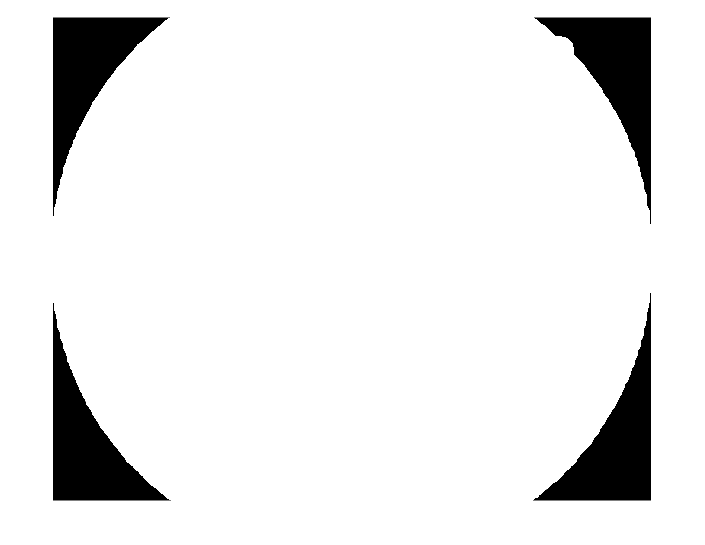

w2 = ones(10);
originalImage = imfilter(originalImage, w2);
originalImage = imfilter(originalImage, w2);
originalImage = imfilter(originalImage, w2);
figure;
imshow(originalImage);

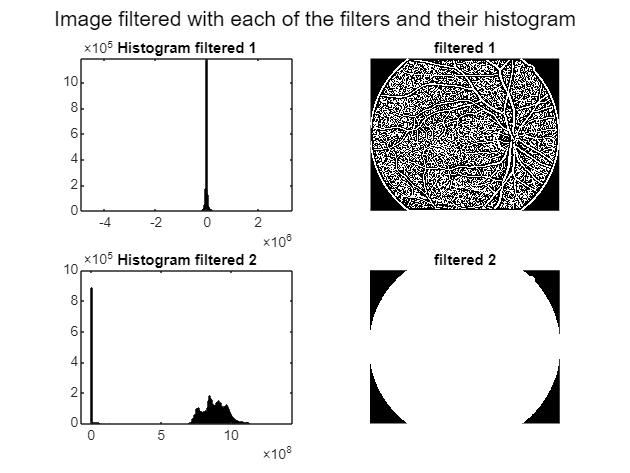


filter1=[1 1 1; 1 -8 1; 1 1 1]; %Este se usa más para el puntu detekzioa
filter2=[0 1 0; 1 4 1; 0 1 0];%Este se usa más para detectar líneas finas

filtered1=imfilter(originalImage,filter1);
filtered2=imfilter(originalImage, filter2);

figure;
sgtitle('Image filtered with each of the filters and their histogram')
subplot(2, 2, 1);
histogram(filtered1);
title('Histogram filtered 1');
subplot(2, 2, 2)
imshow(filtered1)
title('filtered 1');
subplot(2, 2, 3)
histogram(filtered2);
title('Histogram filtered 2');
subplot(2, 2, 4)
imshow(filtered2)
title('filtered 2');

## Step 2 - Divide in layers to see which one corresponds to points and which one corresponds to lines

### Layers of first filtered:

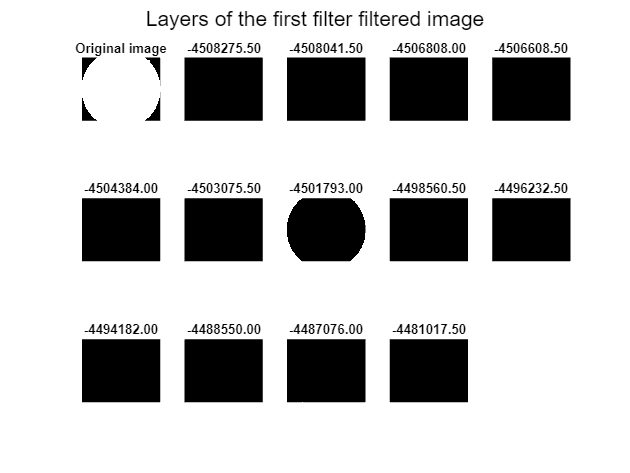

values_filtered1=unique(filtered1);

figure;
sgtitle('Layers of the first filter filtered image');
subplot(3, 5, 1);
imshow(originalImage);
title('Original image');
layers1={};
rango= [-6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6];
for i = 1:length(rango)
    layers = filtered1 == rango(i);
    layers1=[layers1 layers];
    subplot(3, 5, i+1);
    imshow(layers);
    title(sprintf('%.2f', values_filtered1(i)));
end

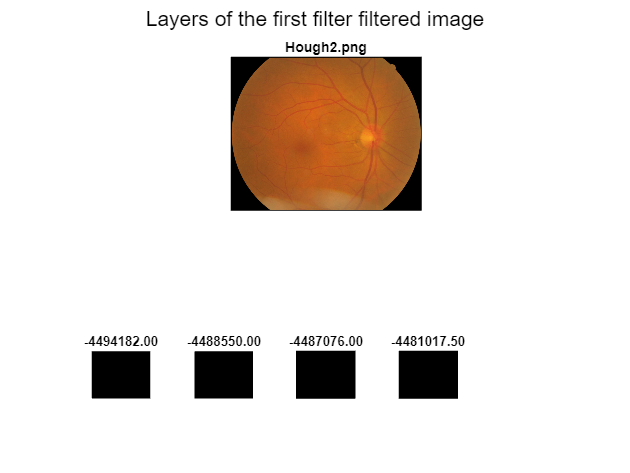

[H,theta,rho] = hough(filtered1);
T=theta;
R=rho;
subplot(2,1,1);
imshow(RGB);
title('Hough2.png');

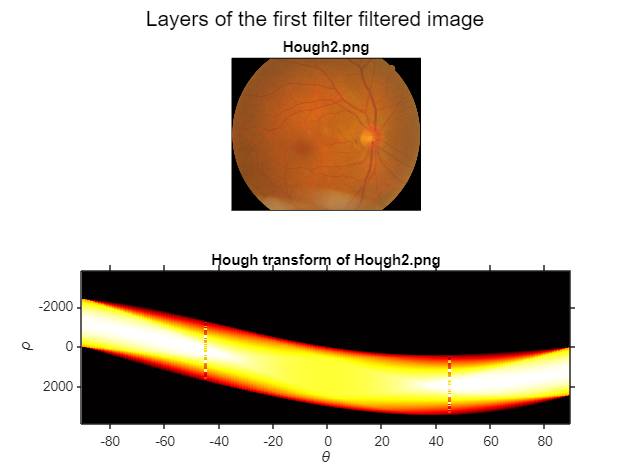

subplot(2,1,2);
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
 'InitialMagnification','fit');
title('Hough transform of Hough2.png');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;
colormap(gca,hot);

P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

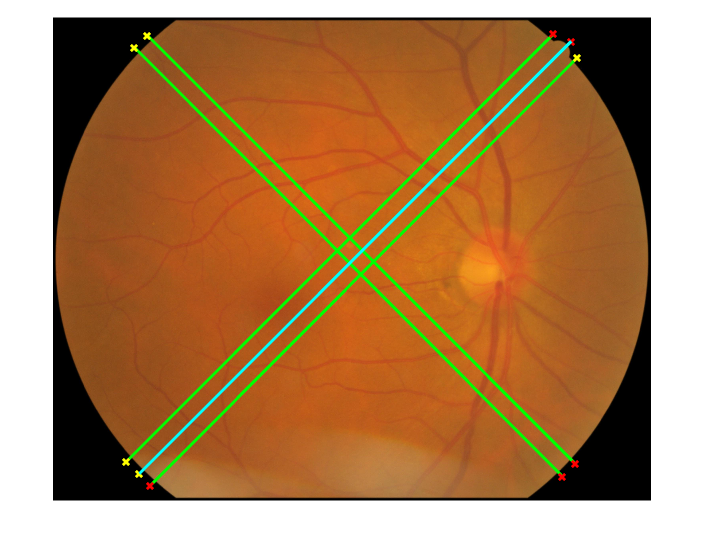


lines = houghlines(filtered1,T,R,P,'FillGap',5,'MinLength',7);
figure, imshow(RGB), hold on
max_len = 0;
for k = 1:length(lines)
 xy = [lines(k).point1; lines(k).point2];
 plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');
 % Plot beginnings and ends of lines
 plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
 plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
 % Determine the endpoints of the longest line segment
 len = norm(lines(k).point1 - lines(k).point2);
 if ( len > max_len)
 max_len = len;
 xy_long = xy;
 end
end


%para poner la línea más larga de cián
plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');